# Figure 3b - Consistency of our data with deVeld

This paper has a published curve showing the mean autofluorescence spectra from the tongue and the cheek.  The original data set, which we sought but could not find, was measured in 96 subjects.  The means across the publication are plotted in the paper, and we scanned the data from the figure.

    *de Veld, D. C., Skurichina, M., Witjes, M. J., Duin, R. P., Sterenborg, D. J., Star, W. M., & Roodenburg, J. L. (2003).  Autofluorescence characteristics of healthy oral mucosa at different anatomical sites. Lasers in Surgery and Medicine: The Official Journal of the American Society for Laser Medicine and Surgery, 32(5), 367-376*

The measurements were made over a small field of view using a fiber optic probe.  It had an 8 mm diameter.  We measured over ?? how large a field (2 deg) at some distance (500 mm ??).  That would be about 18 mm.  If it was 1 deg, then 9 mm, so a good match. The measured the cheeck.  We measured the lip.

The instrument claims a wavelength resolution of 1 nm, which we find very suspicious.

The measurements are in some ways consistent with our data

- The slope from 500nm-600nm is very similar in the two datasets

- We both see a 580 nm dip for the blood

- We both see the porphyrin peak around 640 nm

but do not match perfectly.  

- We see an uptick on the lip around 600nm which they do not report on their cheek

- We see a second peak on the tongue in some of our subjects at 670 nm which is not present on their mean

- We see a clear 540nm dip for blood on both lip and tongue; they do not.

ieInit;
waves = 500:5:700;
symbols = {'kx-','k*-','k^-','ko-'};
T = oeDatabaseCreate;

## Lip, all subjects at 405 nm

Read in the files at all excitation levels and all subjects

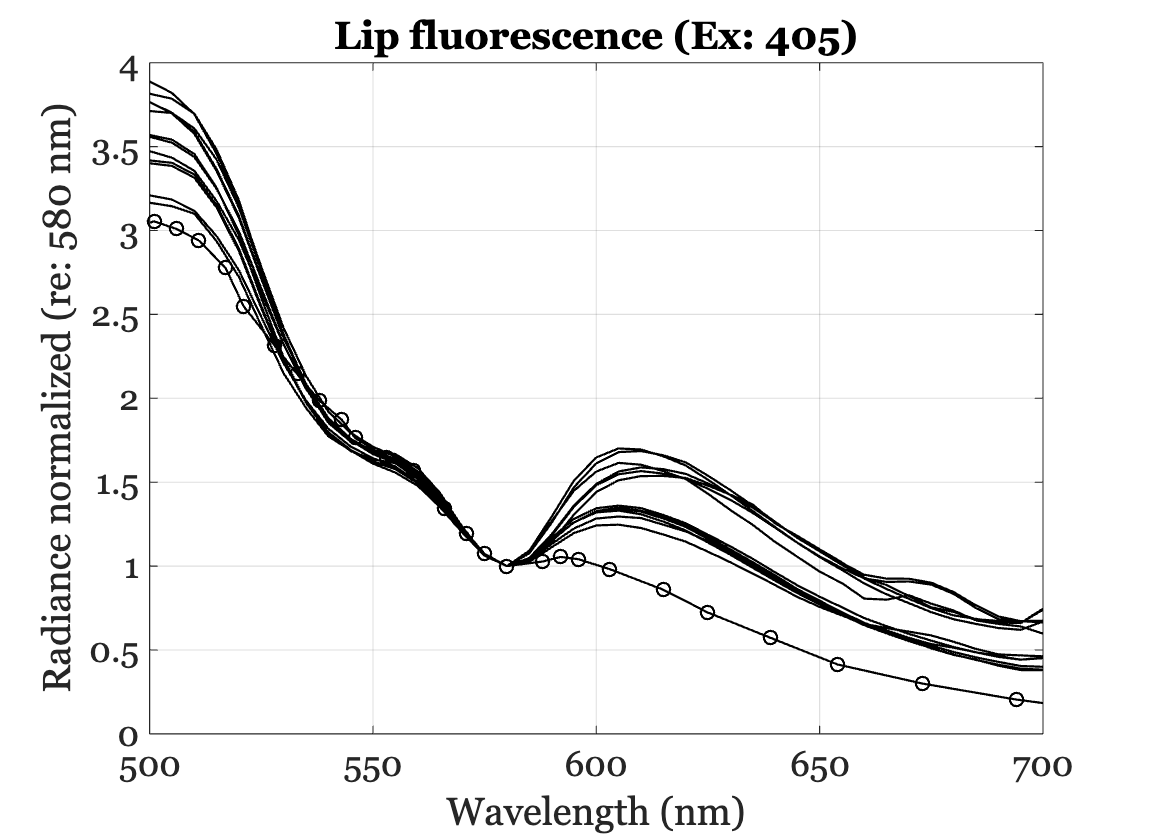

[veldCheekS,wave] = ieReadSpectra('CheekVeld2003.mat'); 
wave = round(wave);
veldCheek = ieReadSpectra('CheekVeld2003.mat',waves); 

eWave = 405;
files405 = ieTableGet(T,...
    'substrate','lip', ...
    'ewave',eWave);

data405 = oeReadFiles(files405,'waves',waves,'normalized wave',580);

ieFigure;
plot(waves,data405,'k-'); hold on;
plot(wave,veldCheekS/veldCheekS(wave == 580),'ko-');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on; set(gca,'xlim',[500 700]);
title('Lip fluorescence (Ex: 405)');

## Fit deVeld cheek from our lip data

veldCheek = data405 * wgts

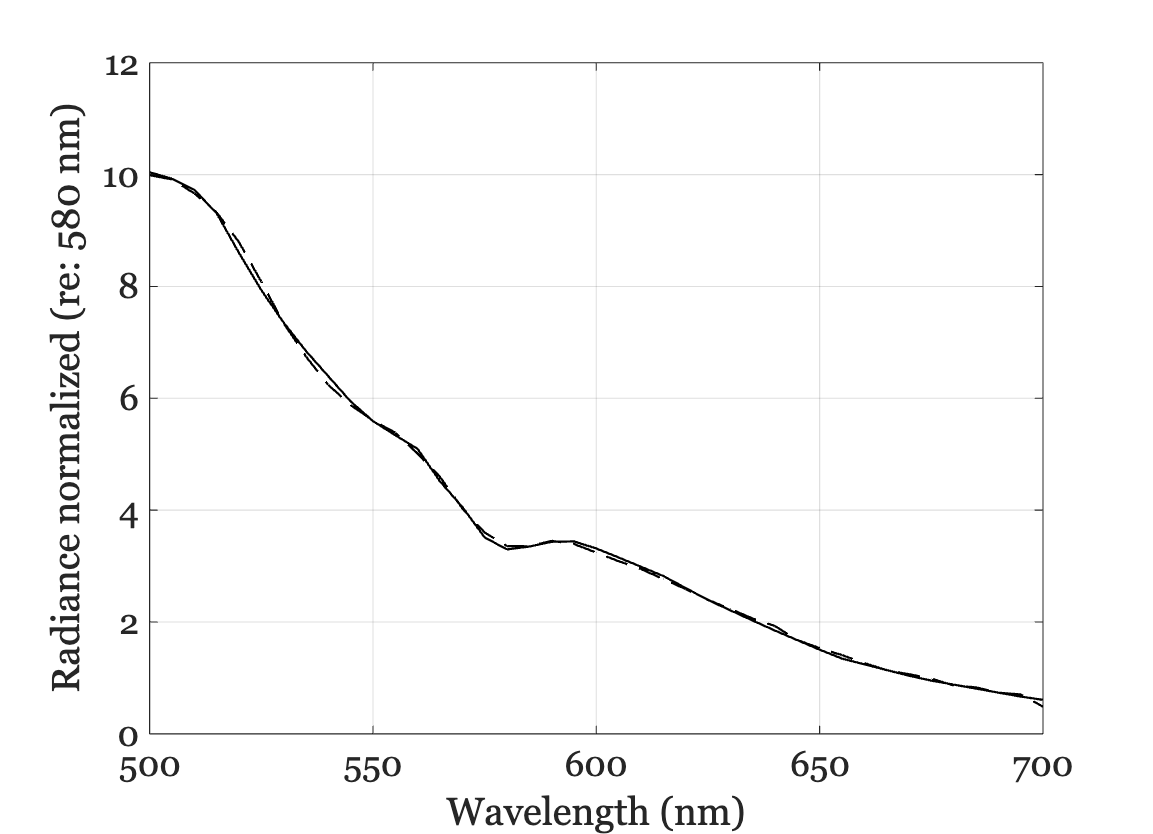

wgts = pinv(data405)*veldCheek;
veldCheekP = data405*wgts;

ieFigure;
plot(waves,veldCheek,'k-',waves,veldCheekP,'k--');
grid on;
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');

## Tongue, all subjects at 405 nm

Read in the files at all excitation levels

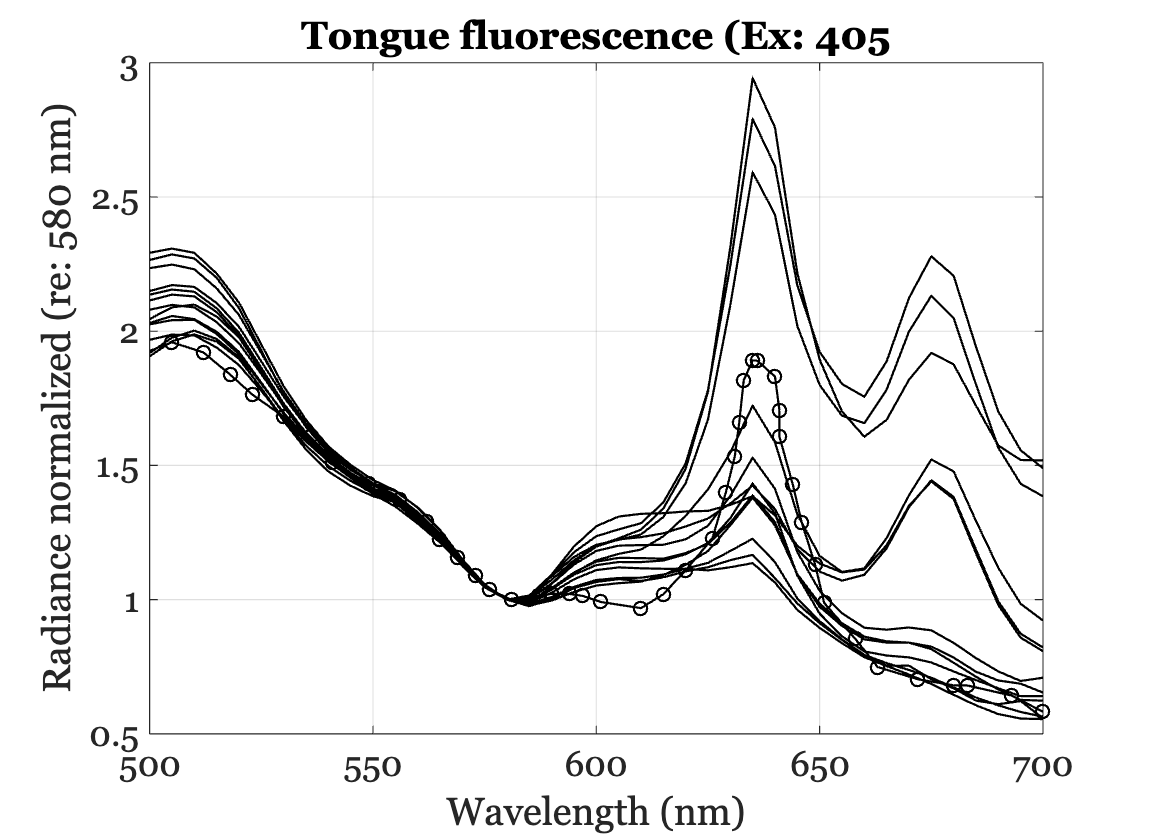

[veldTongueS, wave] = ieReadSpectra('TongueVeld2003.mat');
wave = round(wave);
veldTongue = ieReadSpectra('TongueVeld2003.mat',waves); 

eWave = 405;
files405 = ieTableGet(T,...
    'substrate','tongue', ...
    'ewave',eWave);

data405 = oeReadFiles(files405,'waves',waves,'normalized wave',580);

ieFigure;
plot(waves,data405,'k-'); hold on;
plot(wave,veldTongueS/veldTongueS(wave == 581),'ko-');
xlabel('Wavelength (nm)'); ylabel('Radiance normalized (re: 580 nm)');
set(gca,'xlim',[500 700]); grid on;
title('Tongue fluorescence (Ex: 405');

## Fit deVeld tongue from our tongues data

veldTongue = data405 * wgts

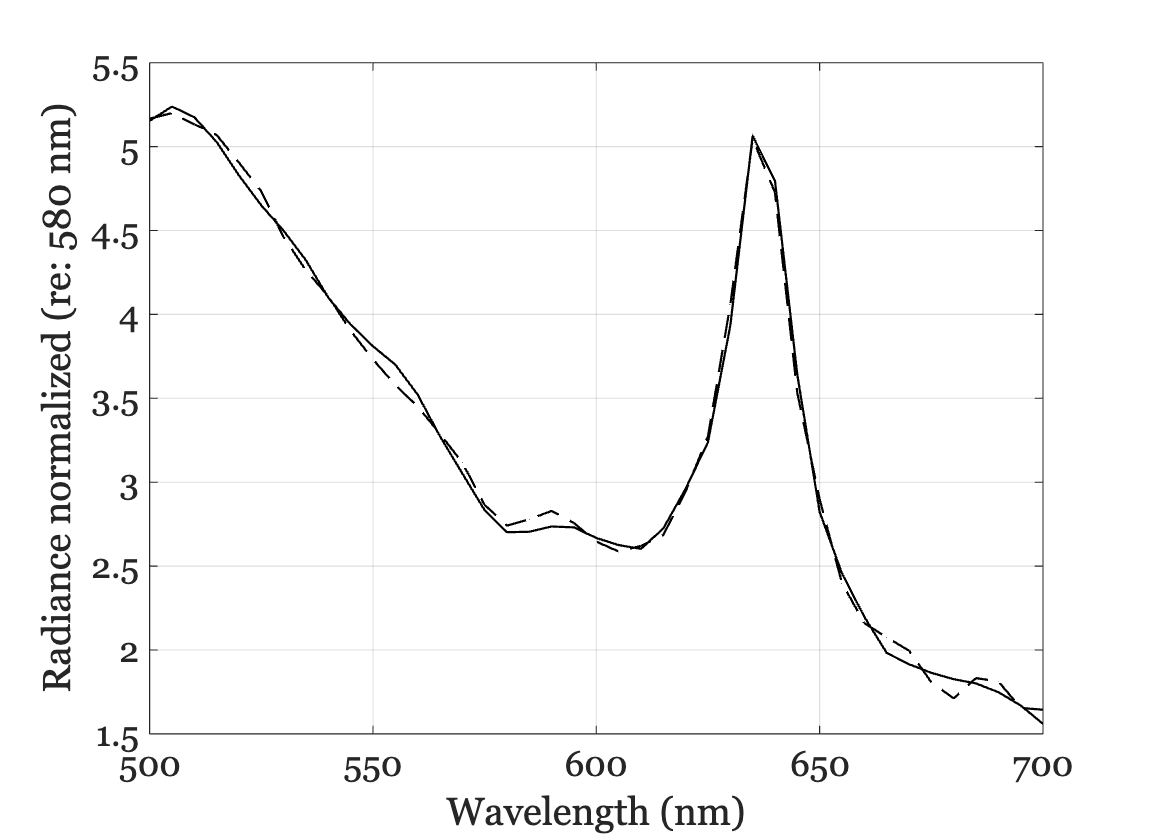

wgts = pinv(data405)*veldTongue;
veldTongueP = data405*wgts;

ieFigure;
plot(waves,veldTongue,'k-',waves,veldTongueP,'k--');
grid on;
xlabel('Wavelength (nm)'); ylabel('Radiance normalized (re: 580 nm)');